NO FINISHED REVISION

 Kalman filters represent the state at time t by the mean $\mu$ and the covariance $\Sigma$. 

These parameters represent the mean and variance of a multivariate Gaussian distribution. So We can say that after execute Kalman filter We will have  multiple posible poses defined by $\Sigma$ however the most likly  is  $\mu$.

The state is  a pose defined by $\left\lbrack x\;\;y\;\;\theta \right\rbrack$ and Coaviance is a 3x3 matrix. Trhoughout kalman filter  $\mu$ and  $\Sigma$ are recalculated to get the best state prediction.

Vector state is represented by :  $\vec{x_t } =\left\lbrack \begin{array}{c}
x_t \\
y_t \\
\theta_t 
\end{array}\right\rbrack$

The extended  kalman Filter is divided in two steps, the first one is the Prediction and the second is Update.

### Prediction step:  

#### 
$$\vec{x_t } =g\left({\overrightarrow{x} }_{t-1} ,\overrightarrow{u} \right)+\gamma$$


Where:  

            Function $g$ is a nonlinear function that calculate new state vector. $g\left({\overrightarrow{x} }_{t-1} ,u\right)=\left\lbrack \begin{array}{c}
\theta_t +u_{\theta } \\
x_{t-1} +u_d \cos \left(u_{\theta } \right)\\
y_{t-1} +u_d \sin \left(u_{\theta } \right)
\end{array}\right\rbrack$

           ${\vec{x} }_{t-1}$ is the last state vector.

            $\overrightarrow{u}$ that is a control command $\overrightarrow{u} =\left\lbrack \begin{array}{c}
\theta \\
d
\end{array}\right\rbrack \;\;\mathrm{indicates}\;a\;\mathrm{turn}\;\mathrm{angle}\;\mathrm{and}\;\mathrm{distance}$. 

            $\gamma$ represents the mean of gaussian noise function that  we doesnt know  becaus that noise depend on fisical environment. 

#### 
$$\Sigma_t =G\Sigma_{t-1} G^T +Q$$


Where: 

            $G$ is the jacobi of function $g$ so $G=\left\lbrack \begin{array}{ccc}
1 & 0 & -u_d \sin \left(\theta_t +u_{\theta } \right)\\
0 & 1 & u_d \cos \left(\theta_t +u_{\theta } \right)\\
0 & 0 & 1
\end{array}\right\rbrack$ 

            $Q$ represent a square matrix  wich is the coavariance of noise environmet.

Scince a mobiel robot  usually desnt execute commands like $\overrightarrow{u}$ we change approach to sampling approach.

Sampling approach defind a function that It accepts an initial pose ${\vec{x} }_{t-1}$  and an odometry readings  in time $t-1$ and $t$

as input, and outputs a random $\vec{x_t }$ distributed according to $g$.

We will show how to code this concepts as follow:

Define a odometry reading in time $t-1$

o_1 = [ 2; 2; 0 ];

Define a odometry reading in time $t$

o = [ 5; 5; .7 ];

initial pose

x_1 = [ 3; 3 ; 0];

Alpha arrays is defined by :

                    alpha1  Specifies the expected noise in odometry's rotation estimate from the rotational component of the robot's motion.

                    alpha2  Specifies the expected noise in odometry's rotation estimate from translational component of the robot's motion.

                    alpha3  Specifies the expected noise in odometry's translation estimate from the translational component of the robot's

                    alpha4  Specifies the expected noise in odometry's translation estimate from the rotational component of the robot's motion.

alpha= [ 0.22
         0.001
         0.001
         0.001 ];

Number of samplings

n = 500;

Define a matrix to store all samplings

samples = zeros(3,n); 

Get a random sampling by function sampleOdometry (it returns  a state vector $\vec{x}$and comand $\overrightarrow{u}$ )and show all samplings.

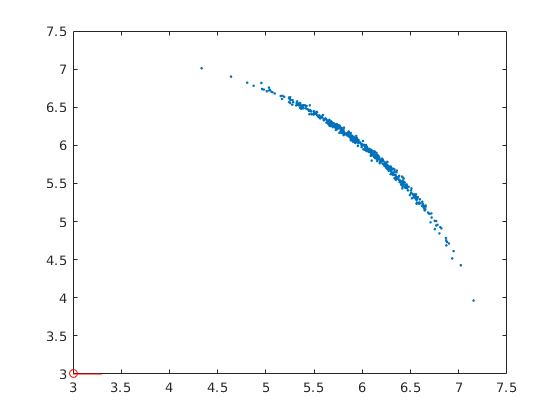

for i=1:n
  [sv, u ] = sampleOdometry(o_1,o,x_1,alpha);
  samples(1,i) =  sv(1); 
  samples(2,i) =  sv(2); 
  samples(3,i) =  sv(3); 
end
r = 0.3;%robot radio

plot( samples(1,:) , samples(2,:),'.');
hold on
plot(x_1(1), x_1(2), 'ro')
plot([x_1(1), x_1(1) + r*cos(x_1(3))], [x_1(2), x_1(2) + r*sin(x_1(3))], 'r-' )
%Uncomment to show posible final robot poses
% for i=1:n
%   plot([samples(1,i) , samples(1,i) + r*cos(samples(3,i))], [samples(2,i), samples(2,i) + r*sin(samples(3,i))], 'r-' )
% end
hold off

In figure above we can see in red the star pose of the robot and execute $\overrightarrow{u}$ command wich change in evrey sampling. The last command sabpling was:

The robots turns 

u(1)

ans = 0.8979

Then advance 

u(2)

ans = 4.2244

Because  alpha1 is  greater than other alphas the resulting sampling show  a density in arc form because  is more probably that the robot makes driffting  while  robot turns.

# Practice

Change all alphas and compare graphs to understand  hos each one affect the sampling.

--------------------

Finnaly The  Prediction step is defined by:

 Q = [0.00001 0  0; 
     0 0.000001  0; 
     0 0  0.00001];
 sigma = [0 0 0; 0 0 0; 0 0 0];
 
 [sv, u] = sampleOdometry(o_1,o,x_1,alpha);
 
 %Jacobian of function g(sv,u)
 G = [ 1 0 -u(2)*sin(u(1));
          0 1  u(2)*cos(u(1));
          0 0         1       ];
  
 sigma =  G*sigma*G.' + Q;

The above will use in next lesson.


% initPose = [ 0.5; 0.5; 1.5707]; % [x ; y ; theta]   
% goalPose = [2; 2.5;0];
% 
% R = 0.1; 
% L = 0.12; 
% 
% viz = Visualizer2D;
% viz.mapName = 'map';
% viz.robotRadius = L; 
% mobileRobot = DifferentialDrive(R,L);
% 

Prepare map  to calculate path

%                        
% [map, mapDilatation]  = generateAugmentedMap(which('world1.png'), 0.1, 10, L); %[path, treshold, scale,robotRadio]
%                 
% [pthObj, solnInfo] = getPathRRT(mapDilatation,initPose,goalPose,0.2,.1,0.2,30000); %[map,initPose,goalPose,MinTurningRadius,ValidationDistance,MaxConnectionDistance,MaxIterations]
%               
% [controller] = controllerPP(pthObj,0.05,0.1,pi/6); %[pthObj,LookaheadDistance,DesiredLinearVelocity,MaxAngularVelocity)]

Execute simulation.

% currentPose = initPose;
% 
% varianceV= 0.01; %.3 
% varianceW= 0.04; % .1
% 
% 
% [sampleTime,tVec,r] = simulTime(0.1,38);
% odom_pose = zeros(3,numel(tVec));
% odom_pose(:,1) = initPose;
% 
% for idx = 2:numel(tVec) 
%       
%     if( sqrt( (odom_pose(1,idx-1)-pthObj.States(end,1))^2 + (odom_pose(2,idx-1)-pthObj.States(end,2))^2 )  < L/2  )
%        break
%     end
%     
%     [v,w,lookAheadPt] = controller(odom_pose(:,idx-1));
% 
%     [wL,wR] = inverseKinematics(mobileRobot,v ,w);
%     
%     % Store each pose computed by odometry
%     odom_pose(:,idx) =  computeOdometry(R,L,wR,wL,sampleTime ,odom_pose(:,idx-1));
%     
%   
%     v = v  + abs(normrnd(0,varianceV));
%     w = w + normrnd(0,varianceW);
%     bodyV = [v ;0;w];    % Body velocities [vx;vy;w]  vy = 0 because the differential robot can not move in y axis.
%     
%     % Convert from robot body to world
%     vel =  bodyToWorld(bodyV,currentPose);  
%    
%     % Perform forward discrete integration step
%     currentPose = currentPose + vel * sampleTime; 
%     
%     % Update visualization
%     viz(currentPose);
% 
%     %Wait for visualization rate
%     waitfor(r);
%     
% end


% hold on
% 
% interpolate(pthObj,300)
% plot(pthObj.States(:,1), pthObj.States(:,2), 'r-', 'LineWidth', 2)
% plot(odom_pose(1,1:idx-1),odom_pose(2,1:idx-1),'g');
% hold off
